Fs = 1e4;%サンプル周波数
t = 0:1/Fs:1;
list = dir('*.csv');
numFiles = length(list);

nharm = 6;%thdの高調波数

%10列2行のセルを作成。1列目にy軸加速度の行列、2列目に力センサ
%（できれば1-の連番にして一々ファイル名を変更しないでも良いようにしたい
Mx = cell(10,2);        %1-10を格納
Mx0 = cell(10,2);       %10-100を格納
Mx50 = cell(10,2);       %150-950を格納
Mx00 = cell(10,2);      %100-1000を格納
G = cell(40,2);


for i = 1:9
    importFile = sprintf('%d.csv', i); %i.csvの名前のファイルをインポート
    Mx{i,1} = csvread(importFile,21,1,[21,1,10020,3]); %ファイル名をi.csvでインポート。21～10020列まで、2～4行目まで
    [Acc_thd_db,Acc_harmpow,Acc_harmfreq] = thd(Mx{i,1}(:,1),Fs,nharm);
    [Tension_thd_db,Tension_harmpow,Tension_harmfreq] = thd(Mx{i,1}(:,2),Fs,nharm);
    [Input_thd_db,Input_harmpow,Input_harmfreq] = thd(Mx{i,1}(:,3),Fs,nharm);
        Mx{i,2}(:,1) = Acc_thd_db;
        Mx{i,2}(:,2) = Tension_thd_db;
        Mx{i,2}(:,3) = Input_thd_db;
        Mx{i,3}(:,1) = Acc_harmpow;
        Mx{i,3}(:,2) = Tension_harmpow;
        Mx{i,3}(:,3) = Input_harmpow;
        Mx{i,4}(:,1) = Acc_harmfreq;
        Mx{i,4}(:,2) = Tension_harmfreq;
        Mx{i,4}(:,3) = Input_harmfreq;
        Mx{i,5}(:,1) = 100*(10^(Acc_thd_db/20));
        Mx{i,5}(:,2) = 100*(10^(Tension_thd_db/20));
        Mx{i,5}(:,3) = 100*(10^(Input_thd_db/20));
        Mx{i,6} = 2*sqrt(2)*rms(Mx{i,1}(:,3));

    G{i,1} = i;%セルの1列目に周波数を入力
    G{i,2}(:,1) = Mx{i,5}(:,1);%グラフ出力用のセルに加速度THD%を入力
    G{i,2}(:,2) = Mx{i,5}(:,2);%グラフ出力用のセルに張力THD%を入力
    G{i,2}(:,3) = Mx{i,5}(:,3);%グラフ出力用のセルに入力VTHD%を入力
end

for i = 1:9
    importFile = sprintf('%d0.csv', i); %i.csvの名前のファイルをインポート
    Mx0{i,1} = csvread(importFile,21,1,[21,1,10020,3]); %ファイル名をi.csvでインポート。21～10020列まで、2～4行目まで
    [Acc_thd_db,Acc_harmpow,Acc_harmfreq] = thd(Mx0{i,1}(:,1),Fs,nharm);
    [Tension_thd_db,Tension_harmpow,Tension_harmfreq] = thd(Mx0{i,1}(:,2),Fs,nharm);
    [Input_thd_db,Input_harmpow,Input_harmfreq] = thd(Mx0{i,1}(:,3),Fs,nharm);
        Mx0{i,2}(:,1) = Acc_thd_db;
        Mx0{i,2}(:,2) = Tension_thd_db;
        Mx0{i,2}(:,3) = Input_thd_db;
        Mx0{i,3}(:,1) = Acc_harmpow;
        Mx0{i,3}(:,2) = Tension_harmpow;
        Mx0{i,3}(:,3) = Input_harmpow;
        Mx0{i,4}(:,1) = Acc_harmfreq;
        Mx0{i,4}(:,2) = Tension_harmfreq;
        Mx0{i,4}(:,3) = Input_harmfreq;
        Mx0{i,5}(:,1) = 100*(10^(Acc_thd_db/20));
        Mx0{i,5}(:,2) = 100*(10^(Tension_thd_db/20));
        Mx0{i,5}(:,3) = 100*(10^(Input_thd_db/20));
    G{i+9,1} = i * 10;%セルの1列目に周波数を入力
    G{i+9,2}(:,1) = Mx0{i,5}(:,1);%グラフ出力用のセルに加速度THD%を入力
    G{i+9,2}(:,2) = Mx0{i,5}(:,2);%グラフ出力用のセルに張力THD%を入力
    G{i+9,2}(:,3) = Mx0{i,5}(:,3);%グラフ出力用のセルに入力VTHD%を入力
end

for i = 1:4
    importFile = sprintf('%d50.csv', i); %i.csvの名前のファイルをインポート
    Mx50{i,1} = csvread(importFile,21,1,[21,1,10020,3]); %ファイル名をi.csvでインポート。21～10020列まで、2～4行目まで
    [Acc_thd_db,Acc_harmpow,Acc_harmfreq] = thd(Mx50{i,1}(:,1),Fs,nharm);
    [Tension_thd_db,Tension_harmpow,Tension_harmfreq] = thd(Mx50{i,1}(:,2),Fs,nharm);
    [Input_thd_db,Input_harmpow,Input_harmfreq] = thd(Mx50{i,1}(:,3),Fs,nharm);
        Mx50{i,2}(:,1) = Acc_thd_db;
        Mx50{i,2}(:,2) = Tension_thd_db;
        Mx50{i,2}(:,3) = Input_thd_db;
        Mx50{i,3}(:,1) = Acc_harmpow;
        Mx50{i,3}(:,2) = Tension_harmpow;
        Mx50{i,3}(:,3) = Input_harmpow;
        Mx50{i,4}(:,1) = Acc_harmfreq;
        Mx50{i,4}(:,2) = Tension_harmfreq;
        Mx50{i,4}(:,3) = Input_harmfreq;
        Mx50{i,5}(:,1) = 100*(10^(Acc_thd_db/20));
        Mx50{i,5}(:,2) = 100*(10^(Tension_thd_db/20));
        Mx50{i,5}(:,3) = 100*(10^(Input_thd_db/20));
    G{i+18,1} = i * 100 + 50;%セルの1列目に周波数を入力
    G{i+18,2}(:,1) = Mx50{i,5}(:,1);%グラフ出力用のセルに加速度THD%を入力
    G{i+18,2}(:,2) = Mx50{i,5}(:,2);%グラフ出力用のセルに張力THD%を入力
    G{i+18,2}(:,3) = Mx50{i,5}(:,3);%グラフ出力用のセルに入力VTHD%を入力
end

for i = 1:5
    importFile = sprintf('%d00.csv', i); %i.csvの名前のファイルをインポート
    Mx00{i,1} = csvread(importFile,21,1,[21,1,10020,3]); %ファイル名をi.csvでインポート。21～10020列まで、2～4行目まで
    [Acc_thd_db,Acc_harmpow,Acc_harmfreq] = thd(Mx00{i,1}(:,1),Fs,nharm);
    [Tension_thd_db,Tension_harmpow,Tension_harmfreq] = thd(Mx00{i,1}(:,2),Fs,nharm);
    [Input_thd_db,Input_harmpow,Input_harmfreq] = thd(Mx00{i,1}(:,3),Fs,nharm);
        Mx00{i,2}(:,1) = Acc_thd_db;
        Mx00{i,2}(:,2) = Tension_thd_db;
        Mx00{i,2}(:,3) = Input_thd_db;
        Mx00{i,3}(:,1) = Acc_harmpow;
        Mx00{i,3}(:,2) = Tension_harmpow;
        Mx00{i,3}(:,3) = Input_harmpow;
        Mx00{i,4}(:,1) = Acc_harmfreq;
        Mx00{i,4}(:,2) = Tension_harmfreq;
        Mx00{i,4}(:,3) = Input_harmfreq;
        Mx00{i,5}(:,1) = 100*(10^(Acc_thd_db/20));
        Mx00{i,5}(:,2) = 100*(10^(Tension_thd_db/20));
        Mx00{i,5}(:,3) = 100*(10^(Input_thd_db/20));
    G{i+27,1} = i * 100;%セルの1列目に周波数を入力
    G{i+27,2}(:,1) = Mx00{i,5}(:,1);%グラフ出力用のセルに加速度THD%を入力
    G{i+27,2}(:,2) = Mx00{i,5}(:,2);%グラフ出力用のセルに張力THD%を入力
    G{i+27,2}(:,3) = Mx00{i,5}(:,3);%グラフ出力用のセルに入力VTHD%を入力
end

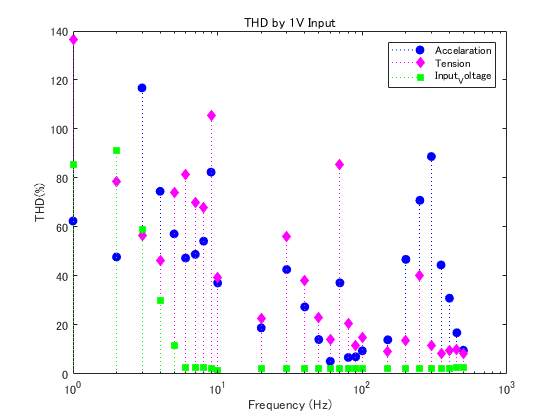


graphdata = cell2mat(G);


stem(graphdata(:,1),graphdata(:,2),'filled','LineStyle',':','Color','b','Marker','o'); %加速度グラフ
hold on
stem(graphdata(:,1),graphdata(:,3),'filled','LineStyle',':','Color','m','Marker','diamond'); %張力のグラフ 
stem(graphdata(:,1),graphdata(:,4),'filled','LineStyle',':','Color','g','Marker','square');  %入力電圧
legend('Accelaration','Tension','Input_Voltage')
set(gca,'xscale','log');    %x軸をlogscaleに
xlabel('Frequency (Hz)');
ylabel('THD(%)');
title('THD by 1V Input');